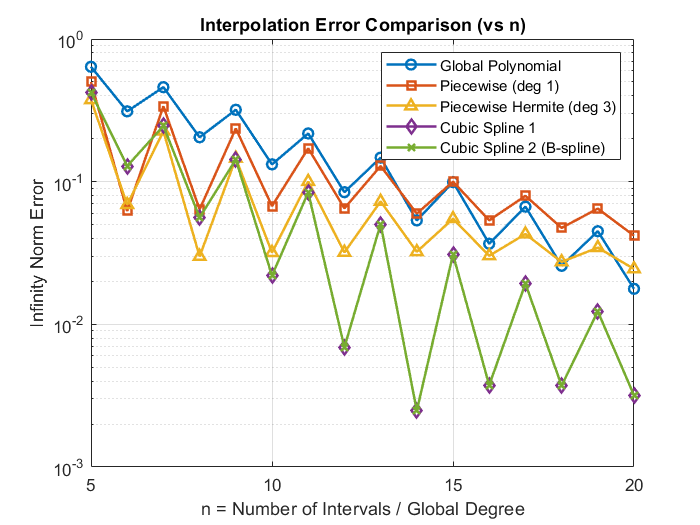

% === Function and derivative ===
k = 25;
f = @(x) 1 ./ (1 + k * x.^2);
f_prime = @(x) (-k * x) ./ ((1 + k * x.^2).^2);

% === Interval and plotting config ===
a = -1; b = 1;
ncheck = 1000;
s_piecewise = 1;                          % Degree for piecewise interpolation
node_type_global = 'chebyshev2';
node_type_piecewise = 'uniform';
bd_type = 'first';
boundary_conditions = (1 / 26^2) * [25, -25];

% === Storage ===
ns = 5:20;
err_global   = zeros(size(ns));
err_piecewise = zeros(size(ns));
err_hermite  = zeros(size(ns));
err_spline1  = zeros(size(ns));
err_spline2  = zeros(size(ns));

for i = 1:length(ns)
    n = ns(i);

    % Run the unified function
    [xcheck, ftrue, p_global, p_piecewise, p_hermite, s1, s2] = ...
        run_all_interpolants(f, f_prime, ...
            a, b, ...
            n, node_type_global, ...
            n, s_piecewise, node_type_piecewise, ...
            bd_type, boundary_conditions, ...
            ncheck);

    % Force column vectors to avoid shape issues
    ftrue = ftrue(:);
    err_global(i)    = max(abs(p_global(:)     - ftrue));
    err_piecewise(i) = max(abs(p_piecewise(:)  - ftrue));
    err_hermite(i)   = max(abs(p_hermite(:)    - ftrue));
    err_spline1(i)   = max(abs(s1(:)           - ftrue));
    err_spline2(i)   = max(abs(s2(:)           - ftrue));
end

%% === Plotting ===
figure('Color', 'w');
semilogy(ns, err_global,    '-o', 'LineWidth', 1.5); hold on;
semilogy(ns, err_piecewise, '-s', 'LineWidth', 1.5);
semilogy(ns, err_hermite,   '-^', 'LineWidth', 1.5);
semilogy(ns, err_spline1,   '-d', 'LineWidth', 1.5);
semilogy(ns, err_spline2,   '-x', 'LineWidth', 1.5);
grid on;

xlabel('n = Number of Intervals / Global Degree');
ylabel('Infinity Norm Error');
title('Interpolation Error Comparison (vs n)');
legend({ ...
    'Global Polynomial', ...
    ['Piecewise (deg ', num2str(s_piecewise), ')'], ...
    'Piecewise Hermite (deg 3)', ...
    'Cubic Spline 1', ...
    'Cubic Spline 2 (B-spline)'}, ...
    'Location', 'northeast');


% Optional: export
% saveas(gcf, 'error_vs_n_plot.png');




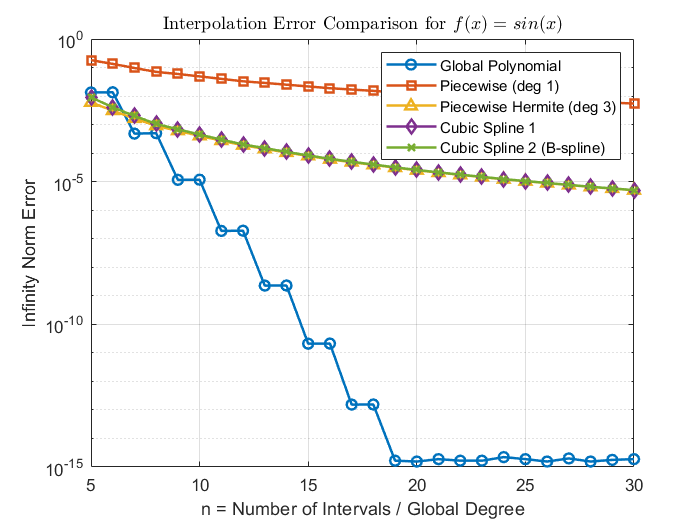

% === Function and derivative for sin(x) ===
f = @(x) sin(x);
f_prime = @(x) cos(x);

% === Interval and plotting config ===
a = -pi;
b = pi;
ncheck = 1000;
s_piecewise = 1;
node_type_global = 'chebyshev2';
node_type_piecewise = 'chebyshev2';
bd_type = 'second';
boundary_conditions = -1*[sin(a), sin(b)];  % f''(a), f''(b) for sin(x)

% === Storage ===
ns = 5:30;
err_global   = zeros(size(ns));
err_piecewise = zeros(size(ns));
err_hermite  = zeros(size(ns));
err_spline1  = zeros(size(ns));
err_spline2  = zeros(size(ns));

for i = 1:length(ns)
    n = ns(i);

    [xcheck, ftrue, p_global, p_piecewise, p_hermite, s1, s2] = ...
        run_all_interpolants(f, f_prime, ...
            a, b, ...
            n, node_type_global, ...
            n, s_piecewise, node_type_piecewise, ...
            bd_type, boundary_conditions, ...
            ncheck);

    ftrue = ftrue(:);
    err_global(i)    = max(abs(p_global(:)     - ftrue));
    err_piecewise(i) = max(abs(p_piecewise(:)  - ftrue));
    err_hermite(i)   = max(abs(p_hermite(:)    - ftrue));
    err_spline1(i)   = max(abs(s1(:)           - ftrue));
    err_spline2(i)   = max(abs(s2(:)           - ftrue));
end

%% === Plotting ===
figure('Color', 'w');
semilogy(ns, err_global,    '-o', 'LineWidth', 1.5); hold on;
semilogy(ns, err_piecewise, '-s', 'LineWidth', 1.5);
semilogy(ns, err_hermite,   '-^', 'LineWidth', 1.5);
semilogy(ns, err_spline1,   '-d', 'LineWidth', 1.5);
semilogy(ns, err_spline2,   '-x', 'LineWidth', 1.5);
grid on;

xlabel('n = Number of Intervals / Global Degree');
ylabel('Infinity Norm Error');
title('Interpolation Error Comparison for $f(x) = \\sin(x)$','Interpreter','latex');
legend({ ...
    'Global Polynomial', ...
    ['Piecewise (deg ', num2str(s_piecewise), ')'], ...
    'Piecewise Hermite (deg 3)', ...
    'Cubic Spline 1', ...
    'Cubic Spline 2 (B-spline)'}, ...
    'Location', 'northeast');

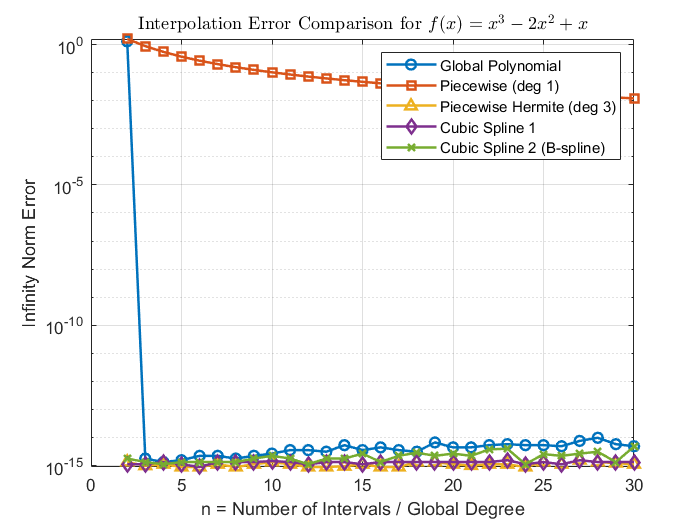

% === Cubic Function and Derivative ===
f = @(x) x.^3 - 2*x.^2 + x;
f_prime = @(x) 3*x.^2 - 4*x + 1;

% === Interval ===
a = -1;
b = 2;

ncheck = 1000;
s_piecewise = 1;
node_type_global = 'chebyshev2';
node_type_piecewise = 'chebyshev2';

% === Boundary conditions for spline ===
bd_type = 'first';
boundary_conditions = [f_prime(a), f_prime(b)];

% === Storage ===
ns = 2:30;
err_global   = zeros(size(ns));
err_piecewise = zeros(size(ns));
err_hermite  = zeros(size(ns));
err_spline1  = zeros(size(ns));
err_spline2  = zeros(size(ns));

for i = 1:length(ns)
    n = ns(i);

    [xcheck, ftrue, p_global, p_piecewise, p_hermite, s1, s2] = ...
        run_all_interpolants(f, f_prime, ...
            a, b, ...
            n, node_type_global, ...
            n, s_piecewise, node_type_piecewise, ...
            bd_type, boundary_conditions, ...
            ncheck);

    ftrue = ftrue(:);
    err_global(i)    = max(abs(p_global(:)     - ftrue));
    err_piecewise(i) = max(abs(p_piecewise(:)  - ftrue));
    err_hermite(i)   = max(abs(p_hermite(:)    - ftrue));
    err_spline1(i)   = max(abs(s1(:)           - ftrue));
    err_spline2(i)   = max(abs(s2(:)           - ftrue));
end

%% === Plotting ===
figure('Color', 'w');
semilogy(ns, err_global,    '-o', 'LineWidth', 1.5); hold on;
semilogy(ns, err_piecewise, '-s', 'LineWidth', 1.5);
semilogy(ns, err_hermite,   '-^', 'LineWidth', 1.5);
semilogy(ns, err_spline1,   '-d', 'LineWidth', 1.5);
semilogy(ns, err_spline2,   '-x', 'LineWidth', 1.5);
grid on;

xlabel('n = Number of Intervals / Global Degree');
ylabel('Infinity Norm Error');
title('Interpolation Error Comparison for $f(x) = \\x^3 - 2x^2 + x$','Interpreter','latex');
legend({ ...
    'Global Polynomial', ...
    ['Piecewise (deg ', num2str(s_piecewise), ')'], ...
    'Piecewise Hermite (deg 3)', ...
    'Cubic Spline 1', ...
    'Cubic Spline 2 (B-spline)'}, ...
    'Location', 'northeast');

**Include this code in the interpolant function if you want to plot a graph of all 5 interpolations:**

    %% ---- Plotting ----

    figure('Name','Interpolation Comparisons','NumberTitle','off');

    % Plot 1: Global Polynomial Interpolation

    subplot(2,3,1);

    plot(xcheck, ftrue, 'k-', 'LineWidth', 1.5); hold on;

    plot(xcheck, pvals_global, 'r--', 'LineWidth', 1.5);

    title('Global Interpolation');

    legend('True', 'Interpolated');

    grid on;

    % Plot 2: Piecewise Interpolation

    subplot(2,3,2);

    plot(xcheck, ftrue, 'k-', 'LineWidth', 1.5); hold on;

    plot(xcheck, pvals_piecewise, 'b--', 'LineWidth', 1.5);

    title(['Piecewise (deg ', num2str(s_piecewise), ')']);

    legend('True', 'Interpolated');

    grid on;

    % Plot 3: Hermite Piecewise

    subplot(2,3,3);

    plot(xcheck, ftrue, 'k-', 'LineWidth', 1.5); hold on;

    plot(xcheck, pvals_hermite, 'm--', 'LineWidth', 1.5);

    title('Piecewise Hermite (deg 3)');

    legend('True', 'Interpolated');

    grid on;

    % Plot 4: Cubic Spline 1

    subplot(2,3,4);

    plot(xcheck, ftrue, 'k-', 'LineWidth', 1.5); hold on;

    plot(xcheck, spline_vals1, 'g--', 'LineWidth', 1.5);

    title('Cubic Spline 1');

    legend('True', 'Interpolated');

    grid on;

    % Plot 5: Cubic Spline 2 (B-spline)

    subplot(2,3,5);

    plot(xcheck, ftrue, 'k-', 'LineWidth', 1.5); hold on;

    plot(xcheck, spline_vals2, 'c--', 'LineWidth', 1.5);

    title('Cubic Spline 2 (B-spline)');

    legend('True', 'Interpolated');

    grid on;